### 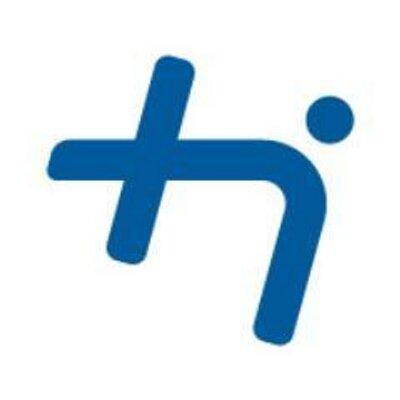**Prof. Dr. Michael Mecking **

#### **Practical Course - Digital Signal Processing / AVE**

# **Analysis of LTI-Systems**

The **z-Transform **of a signal $x[n]$ is given by the relationship


$$X(z) = \sum_{n=-\infty}^{\infty} x[n] \, z^{-n}.$$


For a system described by a linear constant coefficient difference equation (CCDE)


$$\sum_{k=0}^{N} a_k y[n-k] = \sum_{m=0}^{M} b_m x[n-m]$$


the **transfer function **$H(z)$ as z-Transform of the impulse repsonse $h[n]$ is given by

$H(z) = \frac{\sum_{k=0}^M b_k \, z^{-k}}{\sum_{k=0}^N a_k \, z^{-k}}
			    = \frac{b_0 \prod_{k=1}^M (1-c_k \, z^{-1})}{a_0 \prod_{k=1}^N (1-d_k \, z^{-1}) }$.

The $M$ zeroes of the transfer function $H(z)$ are located at $c_k, \, k = 1, \ldots, M$ and the $N$ poles of the transfer function are located at $d_k, \, k = 1, \ldots, N$. 

For a system to be stable and causal, all poles $d_k$ need to be located inside the unit circle, and the region of convergence of $H(z)$ is outside the outermost pole.

## Problem 1.1

Consider the **System 1** given by the rational transfer function


$$H_1(z) = \frac{1}{6}\, \frac{(1-0.98\,e^{j0.8\pi} z^{-1})(1-0.98\,e^{-j0.8\pi} z^{-1}) } {(1-0.8\,e^{j0.4\pi} z^{-1})(1-0.8\,e^{-j0.4\pi}z^{-1}) }.$$


You may find the coefficients $\{a_k\}$and $\{b_m\}$ of the LCCDE describing this system based on the poles and zeroes of the transfer function $H(z)$ using MATLAB's command  *zp2tf (zero-pole to transfer function).*

Find the coefficients $\{b_m\}$ of the numerator polynomial and the coefficients $\{a_k\}$ of the denominator polynomial of the given transfer function $H_1(z)$.

% pole / zeroes to transfer function
% your code...
z =  [0.98*exp(1j*0.8*pi), 0.98*exp(-1j*0.8*pi)]';
p=[0.8*exp(1j*0.4*pi),0.8*exp(-1j*0.4*pi)]';
k=1/6

k = 0.1667

[b,a]=zp2tf(z,p,k)

b =     0.1667    0.2643    0.1601


a =     1.0000   -0.4944    0.6400


### Problem 1.2

Plot the location of the zeores and poles of the transfer function $H_1(z)$ using MATLAB's command *zplane*.

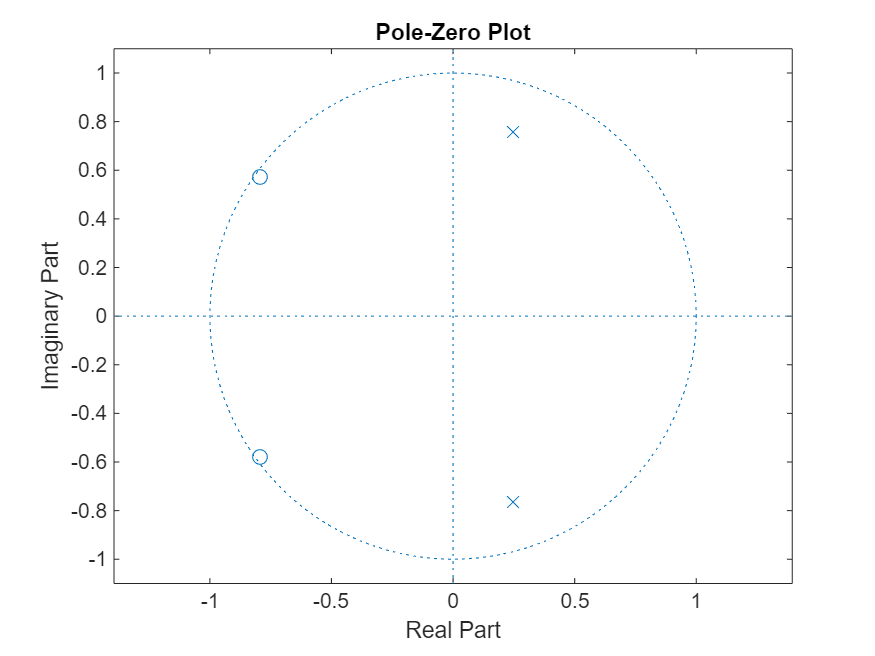

% plot the zeroes and poles of H1(z)
% your code...
figure;
zplane(z,p)

### **Problem 1.3**

Plot and observe the magnitude response $|H_1(e^{j\Omega})|$ and phase response $\arg H_1(e^{j\Omega})$ of System 1.

Would you describe System 1 as having a constant magnitude response or linear phase?

Can you correlate the location of zeroes and poles to the magnitude as well as phase response?

How does the magnitude response change in the vicinity of a pole or a zero?

How does the phase response change in the vicinity of a pole or a zero?

Try to understand the following (simple) computation of the frequency respinse using MATLAB's build in commands!

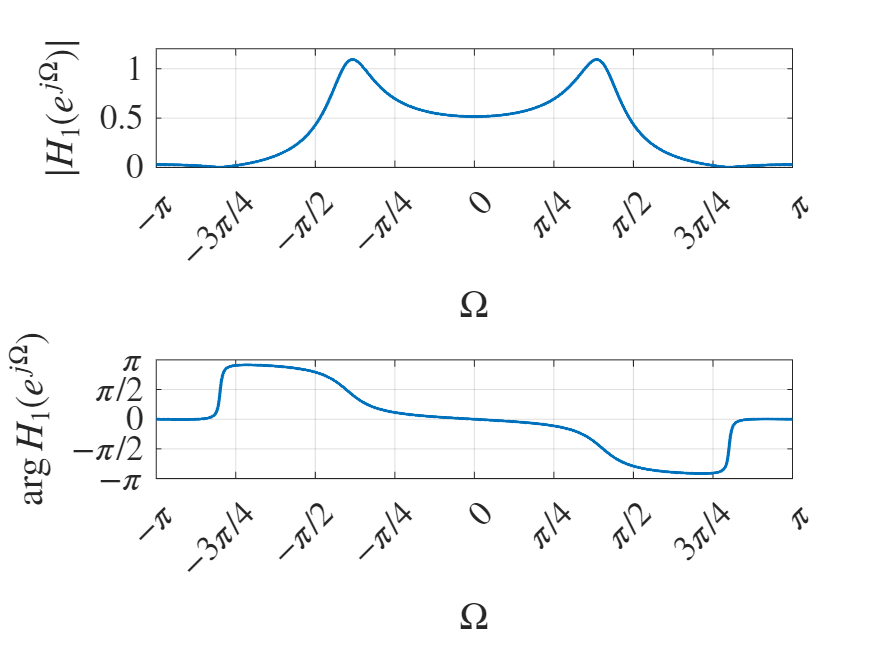

% evaluate the magnitude and phase response of system 1 
% given by coefficient vectors b1 and a1

numf = 2048;
H1   = freqz(b, a, numf, 'whole');  % freqz evaluates the frequency response at numf 
                                      % frequencies equally spaced on the unit circle

H1    = circshift(H1, numf/2);        % we need to circularly shift by half the samples in order to have the 
                                      % frequencies ranging from (-pi, pi).
Omega = linspace(-pi*(1-1/numf), pi, numf);

figure
subplot(2,1,1)
plot(Omega, abs(H1), 'LineWidth',1.5)
axis([-pi pi 0 1.1*max(abs(H1))])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$|H_1(e^{j\Omega})|$", Interpreter="latex")

subplot(2,1,2)
plot(Omega, angle(H1), 'LineWidth',1.5)
axis([-pi pi -pi pi])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
yticks([-pi -pi/2 0 pi/2 pi])
yticklabels({'$-\pi$','$-\pi/2$', '$0$', '$\pi/2$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$\arg H_1(e^{j\Omega})$", Interpreter="latex")

**Observations:**

-  by looking the poles we can see that at the position of 3Pi/2 and -3pi/2 the distinct peaks  

## Problem 2.1

The transfer function of **System 2 **has 8 zeroes and poles. The poles are at locations


$$d_k = 0.95 \, e^{j(0.15\pi+0.02\pi \cdot k)}, \quad k = 1, 2, 3, 4$$


and additionally at the complex-conjugate locations


$$d_{k} = d_{k-4} ^{*}, \quad k = 5,6,7,8.$$


The zeroes are at the complex-conjugate reciprocal locations of the poles, i.e.,


$$c_k = 1/d_k^{*}, \quad 1 \le k \le 8.$$


Plot the pole and zero locations of System 2.

% pole / zeroes of system 2
% your code...

p=0.95*exp(1*1i*(0.15*pi + 0.02*pi*(1:4)))

p =    0.8177 + 0.4836i   0.7857 + 0.5340i   0.7506 + 0.5823i   0.7126 + 0.6282i


p_c= conj(p)

p_c =    0.8177 - 0.4836i   0.7857 - 0.5340i   0.7506 - 0.5823i   0.7126 - 0.6282i


poles=[p,p_c]

poles =    0.8177 + 0.4836i   0.7857 + 0.5340i   0.7506 + 0.5823i   0.7126 + 0.6282i   0.8177 - 0.4836i   0.7857 - 0.5340i   0.7506 - 0.5823i   0.7126 - 0.6282i


z_2=(1./conj(poles))

z_2 =    0.9060 + 0.5358i   0.8706 + 0.5917i   0.8317 + 0.6452i   0.7896 + 0.6961i   0.9060 - 0.5358i   0.8706 - 0.5917i   0.8317 - 0.6452i   0.7896 - 0.6961i


[b2,a2]=zp2tf(z_2',poles,1/1.5073)

b2 =     0.6634   -4.5087   14.4208  -27.9681   35.8275  -30.9895   17.7050   -6.1335    1.0000


a2 =     1.0000   -6.1334   17.7045  -30.9887   35.8265  -27.9673   14.4205   -4.5086    0.6634


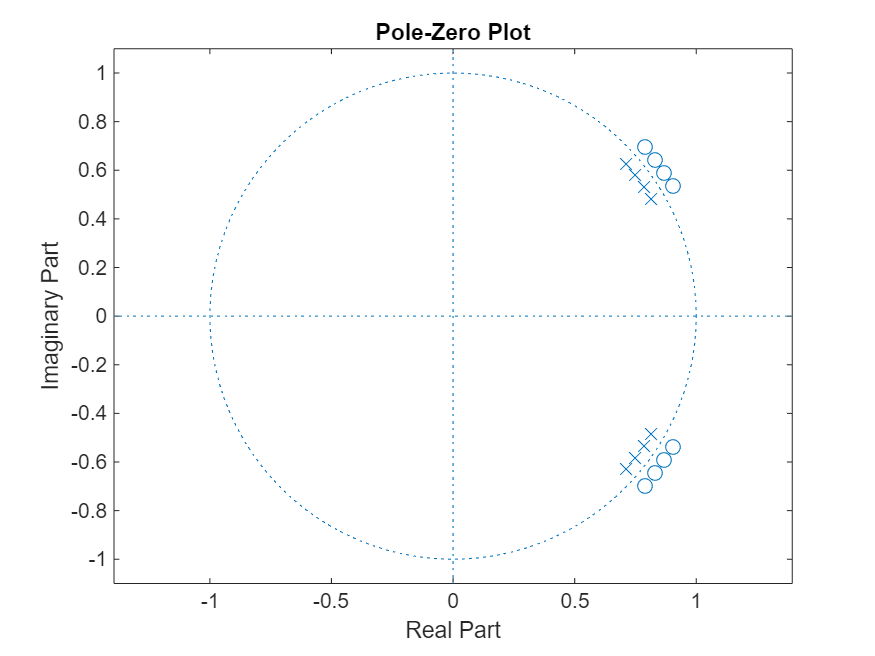

figure;
zplane(b2,a2)

### **Problem 2.2**

Plot the magnitude and phase response of System 2. The magnitude response of System 2 is to be normalised so that $H_2(e^{j0}) = 1$.

What do you observe looking at the magnitude and phase response of System 2 (taking into account the pole/zero locations)?

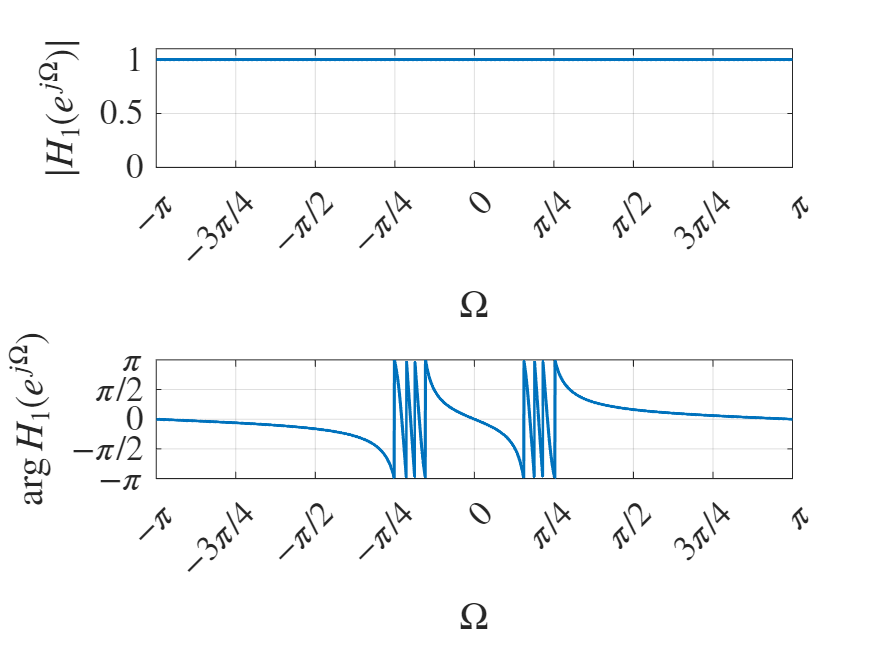

% your code...
% evaluate the magnitude and phase response of system 1 
% given by coefficient vectors b1 and a1

numf = 2048;
H1   = freqz(b2, a2, numf, 'whole');  % freqz evaluates the frequency response at numf 
                                      % frequencies equally spaced on the unit circle

H1    = circshift(H1, numf/2);        % we need to circularly shift by half the samples in order to have the 
                                      % frequencies ranging from (-pi, pi).
Omega = linspace(-pi*(1-1/numf), pi, numf);

figure
subplot(2,1,1)
plot(Omega, abs(H1), 'LineWidth',1.5)
axis([-pi pi 0 1.1*max(abs(H1))])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$|H_1(e^{j\Omega})|$", Interpreter="latex")

subplot(2,1,2)
plot(Omega, angle(H1), 'LineWidth',1.5)
axis([-pi pi -pi pi])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
yticks([-pi -pi/2 0 pi/2 pi])
yticklabels({'$-\pi$','$-\pi/2$', '$0$', '$\pi/2$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$\arg H_1(e^{j\Omega})$", Interpreter="latex")

**Observations:**

- the magnitude is behave like a allpass filter 

- Phase responce say that if we start for the 0 to the down side we can see at pi/4 there we can see frequences distur

## Problem 3.1

The following signal $x[n]$ is to be processed by a serial concatenation of Systems 1 and System 2. The signal $x[n]$ comprised three sine-signals


$$x_1[n] = w[n] \cdot \cos(0.2\pi n)$$



$$x_2[n] = w[n] \cdot \cos(0.4\pi n - \pi/2)$$



$$x_3[n] = w[n] \cdot \cos(0.8\pi n + \pi/5)$$


with the window-signal $w[n]$ given by the so called Hamming-window


$$w[n] = 0.54 - 0.46 \cos \left( \frac{2\pi \, n}{M} \right), \quad 0 \le n \le M, \quad M = 60.$$


The input signal $x[n]$ is then evaluated as the superposition of the three sine-signals with appropriate delays


$$x[n] = x_3[n] + x_1[n-M-1] + x_2[n-2M-2].$$


Plot the signal $x[n]$ (we use MATLAB's *plot* command, not *stem*, this time - mind that the signal is nevertheless discrete-time!) as well as the magnitude response $|X(e^{j\Omega})|$ of $x[n]$.

Can you discern the three pulses of different frequencies in the time- as well as frequency-domain? 

Note that the blurring of the discrete cosine-frequencies in the frequency domain is due to the multiplication with the window $w[n]$ corresponding to a convolution in the frequency domain!

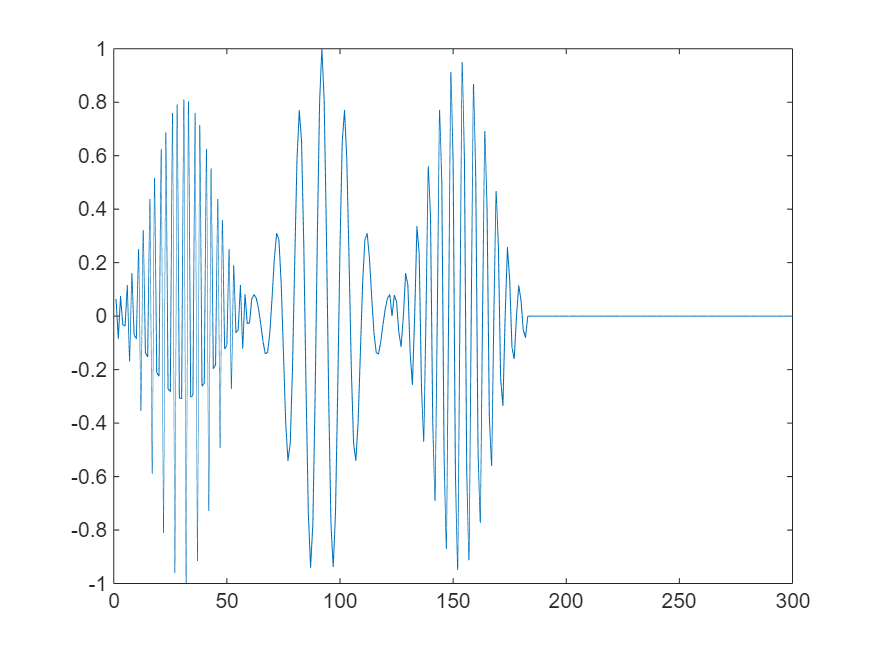

% generation of the signal x[n]
n  = 0:1:60;
w  = hamming(61);
x1 = w' .* cos(0.2*pi*n);
x2 = w' .* cos(0.4*pi*n - pi/2);
x3 = w' .* cos(0.8*pi*n + pi/5);
x = [x3 x1 x2 zeros(1,117)]; % zeros appended to make signal length = 300 samples

% plot of x[n] and magnitude of frequency response of x[n]
% your code...

figure;
plot(x)


numf = 2048;
X = fft(x,numf)

X =    0.1447 + 0.0000i   0.1449 - 0.0206i   0.1440 - 0.0444i   0.1381 - 0.0728i   0.1228 - 0.1039i   0.0948 - 0.1329i   0.0542 - 0.1530i   0.0050 - 0.1574i  -0.0452 - 0.1419i  -0.0866 - 0.1066i  -0.1104 - 0.0567i  -0.1108 - 0.0014i  -0.0873 + 0.0476i  -0.0451 + 0.0795i   0.0056 + 0.0874i   0.0522 + 0.0697i   0.0829 + 0.0315i   0.0895 - 0.0170i   0.0699 - 0.0628i   0.0285 - 0.0935i  -0.0248 - 0.1003i  -0.0772 - 0.0803i  -0.1163 - 0.0370i  -0.1330 + 0.0207i  -0.1235 + 0.0807i  -0.0903 + 0.1314i  -0.0408 + 0.1639i   0.0150 + 0.1743i   0.0670 + 0.1638i   0.1079 + 0.1380i   0.1342 + 0.1043i   0.1468 + 0.0699i   0.1496 + 0.0397i   0.1476 + 0.0150i   0.1446 - 0.0057i   0.1421 - 0.0259i   0.1384 - 0.0487i   0.1299 - 0.0751i   0.1122 - 0.1031i   0.0829 - 0.1278i   0.0428 - 0.1426i  -0.0036 - 0.1415i  -0.0483 - 0.1216i  -0.0822 - 0.0842i  -0.0975 - 0.0354i  -0.0898 + 0.0149i  -0.0605 + 0.0555i  -0.0162 + 0.0768i   0.0319 + 0.0735i   0.0715 + 0.0464i



X   = circshift(X, numf/2);
x_mag = abs(X)

x_mag =     0.0153    0.0263    0.0463    0.0691    0.0937    0.1187    0.1426    0.1638    0.1802    0.1904    0.1931    0.1874    0.1734    0.1516    0.1240    0.0939    0.0693    0.0653    0.0861    0.1168    0.1471    0.1727    0.1911    0.2012    0.2028    0.1961    0.1823    0.1628    0.1393    0.1137    0.0878    0.0629    0.0402    0.0212    0.0158    0.0309    0.0516    0.0745    0.0985    0.1225    0.1447    0.1633    0.1767    0.1834    0.1822    0.1727    0.1552    0.1308    0.1022    0.0749



f = linspace(-pi,pi,numf)

f =    -3.1416   -3.1385   -3.1355   -3.1324   -3.1293   -3.1262   -3.1232   -3.1201   -3.1170   -3.1140   -3.1109   -3.1078   -3.1048   -3.1017   -3.0986   -3.0956   -3.0925   -3.0894   -3.0863   -3.0833   -3.0802   -3.0771   -3.0741   -3.0710   -3.0679   -3.0649   -3.0618   -3.0587   -3.0556   -3.0526   -3.0495   -3.0464   -3.0434   -3.0403   -3.0372   -3.0342   -3.0311   -3.0280   -3.0250   -3.0219   -3.0188   -3.0157   -3.0127   -3.0096   -3.0065   -3.0035   -3.0004   -2.9973   -2.9943   -2.9912


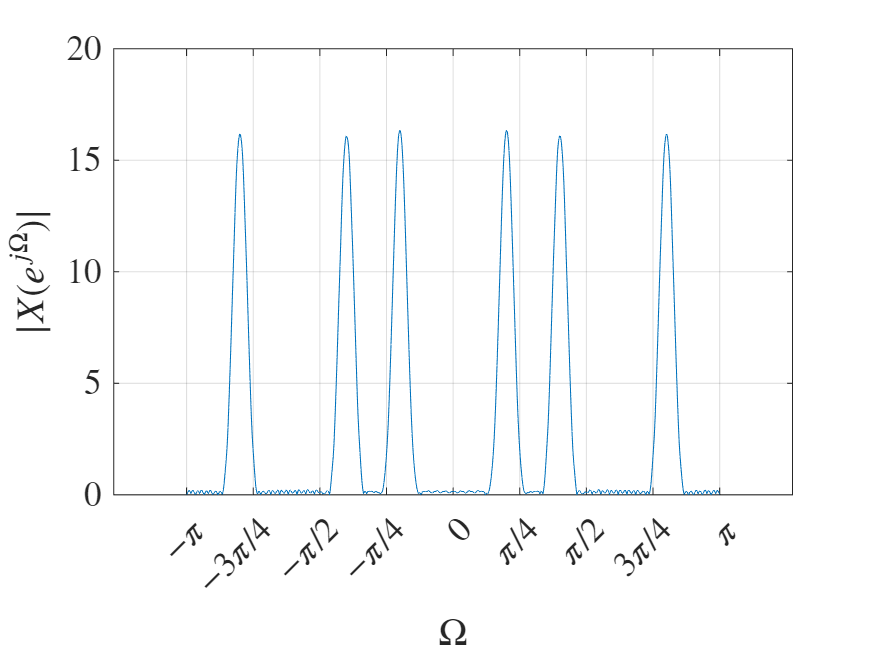


plot(f,x_mag)
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$|X(e^{j\Omega})|$", Interpreter="latex")

### **Problem 3.2**

Process the signal $x[n]$ by the cascade of System1 and two-times System 2 (MATLAB's command *filter* might come in handy - check the usage using MATLAB's documentation).

Plot the output signal $y_1[n]$ of System 1 and the output signal $y_2[n]$ after the cascade with (two-times!) System 2. 

Comment on the results! 

What do you observe after system 1 has processed the signal, and how do you explain the changes in the signal imposed by system 2?

% filter the signal x[n] by systems 1 and 2
% your code...
y1=filter(b,a,x)

y1 =     0.0108    0.0087   -0.0019   -0.0057   -0.0045    0.0057    0.0021   -0.0019    0.0013   -0.0053    0.0048   -0.0001   -0.0026    0.0044   -0.0062    0.0047   -0.0006   -0.0031    0.0055   -0.0062    0.0042   -0.0004   -0.0030    0.0049   -0.0049    0.0029    0.0000   -0.0023    0.0032   -0.0026    0.0011    0.0004   -0.0011    0.0008    0.0000   -0.0007    0.0007    0.0002   -0.0015    0.0024   -0.0022    0.0008    0.0013   -0.0031    0.0038   -0.0028    0.0006    0.0019   -0.0037    0.0038


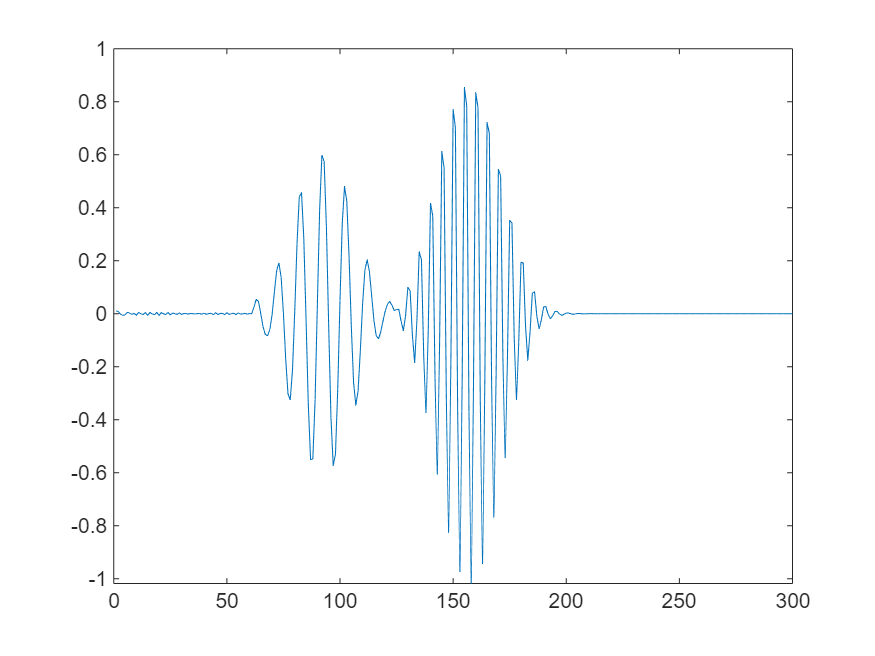

plot(y1)

y2=filter(b2,a2,y1)

y2 =     0.0072    0.0010   -0.0053   -0.0005    0.0050    0.0105   -0.0001   -0.0047    0.0001   -0.0033    0.0072   -0.0004   -0.0026    0.0026   -0.0078    0.0039   -0.0024   -0.0020    0.0062   -0.0048    0.0058   -0.0012   -0.0027    0.0042   -0.0052    0.0037   -0.0004   -0.0018    0.0028   -0.0036    0.0007   -0.0004   -0.0009    0.0018    0.0009    0.0004    0.0013   -0.0003   -0.0020    0.0013   -0.0031    0.0009    0.0010   -0.0023    0.0042   -0.0030    0.0012    0.0012   -0.0034    0.0042



y3=filter(b2,a2,y2)

y3 =     0.0047   -0.0025   -0.0041    0.0037    0.0061    0.0054   -0.0056   -0.0033    0.0055    0.0022    0.0083   -0.0035   -0.0038    0.0024   -0.0053    0.0067   -0.0023   -0.0020    0.0032   -0.0078    0.0041   -0.0026   -0.0007    0.0057   -0.0038    0.0046   -0.0015   -0.0018    0.0027   -0.0029    0.0023    0.0001   -0.0012    0.0003   -0.0015   -0.0013    0.0006    0.0002    0.0002    0.0031   -0.0018    0.0016   -0.0002   -0.0029    0.0033   -0.0035    0.0019    0.0008   -0.0032    0.0035


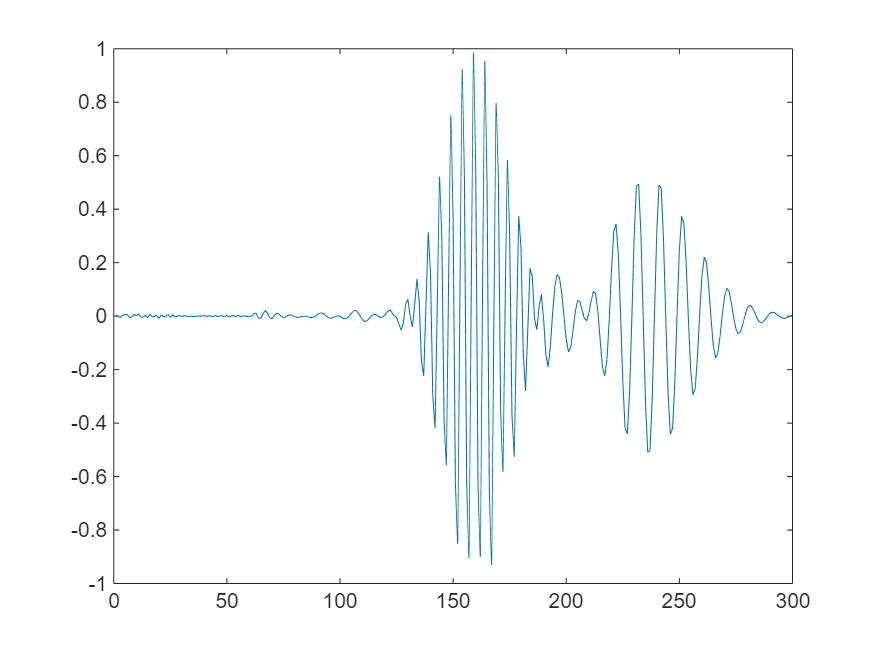

    plot(y3)

    y4=filter(b2,a2,y3)

y4 =     0.0031   -0.0037   -0.0018    0.0055    0.0034    0.0001   -0.0067    0.0017    0.0088    0.0012    0.0039   -0.0064   -0.0005    0.0067   -0.0015    0.0073   -0.0049   -0.0026    0.0024   -0.0064    0.0061   -0.0029   -0.0009    0.0027   -0.0065    0.0035   -0.0020    0.0005    0.0044   -0.0019    0.0026   -0.0010   -0.0013    0.0009   -0.0004    0.0002    0.0010   -0.0010   -0.0015    0.0007   -0.0031    0.0020    0.0006   -0.0008    0.0043   -0.0034    0.0020   -0.0003   -0.0028    0.0039


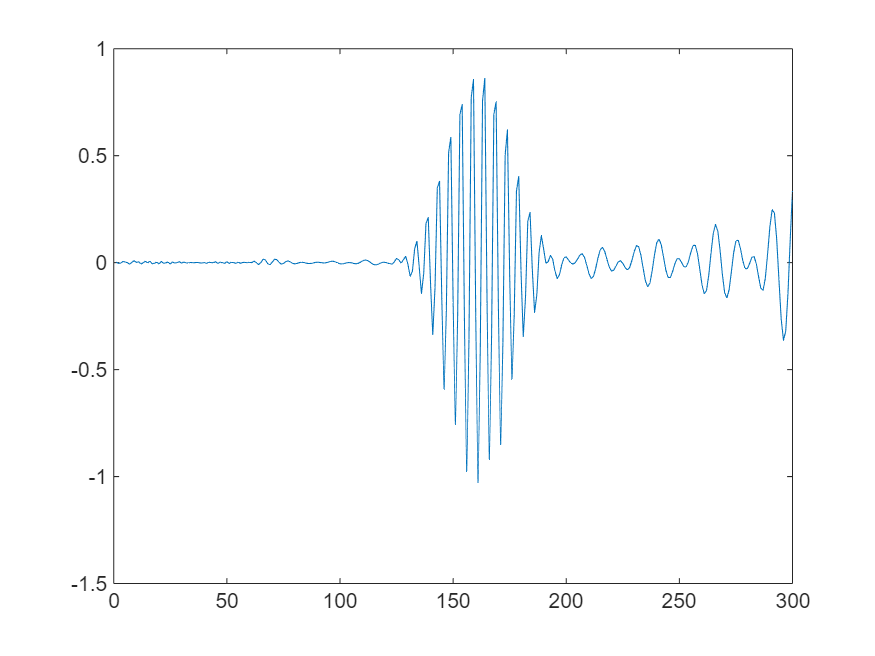

    plot(y4)





    [M,I]=max(X)
    OmegaMax=Omega(I)
    p=[0.99*exp(1i*OmegaMax) 0.99*exp(-1i*OmegaMax)];
z=[exp(1i*OmegaMax) exp(-1i*OmegaMax)]